clear all
close all
%pose.mat
%Objective of Task2: Use PCA and/or MDA for preprocessing and (i)BayesUse 
% PCA and/or MDA for preprocessing and (i)Bayes's and (ii) k-NN classifiers.  
% Feel free to start with just a few subjects.  You can use the first 10poses 
% for each subject for training set and the last three for test set.  
% Experiment with preprocessingand with classifiers trying to maximize 
% correct classification.  You also might want to experimentwith 
% illumination effects.s and (ii) k-NN classifiers.  Feel free to 
% start with just a few subjects.  You can use the first 10poses for 
% each subject for training set and the last three for test set.  
% Experiment with preprocessingand with classifiers trying to maximize 
% correct classification.  You also might want to experiment with 
% illumination effects.

data = load('pose.mat');
pose = data.pose;

%subject1 = pose(:,:,1:13,1); -- this is subject one numerical code;

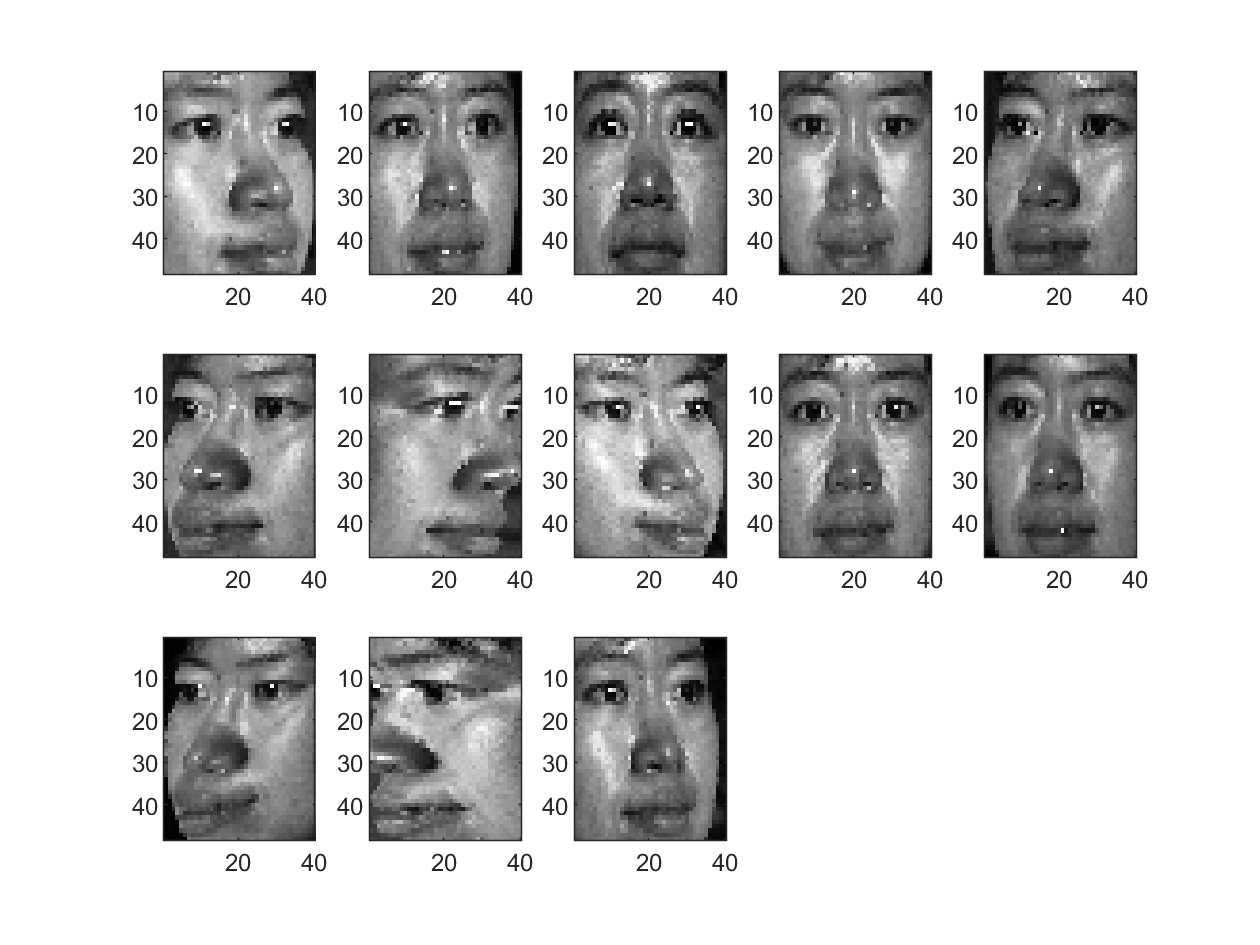

figure; %subject 1 images -- all 13 poses
colormap gray
for j = 1:13
    subject1 = subplot(3,5,j);imagesc(reshape(pose(:,:,j,1),[48 40]));
end
figure; %subject 2 images -- all 13 poses
colormap gray

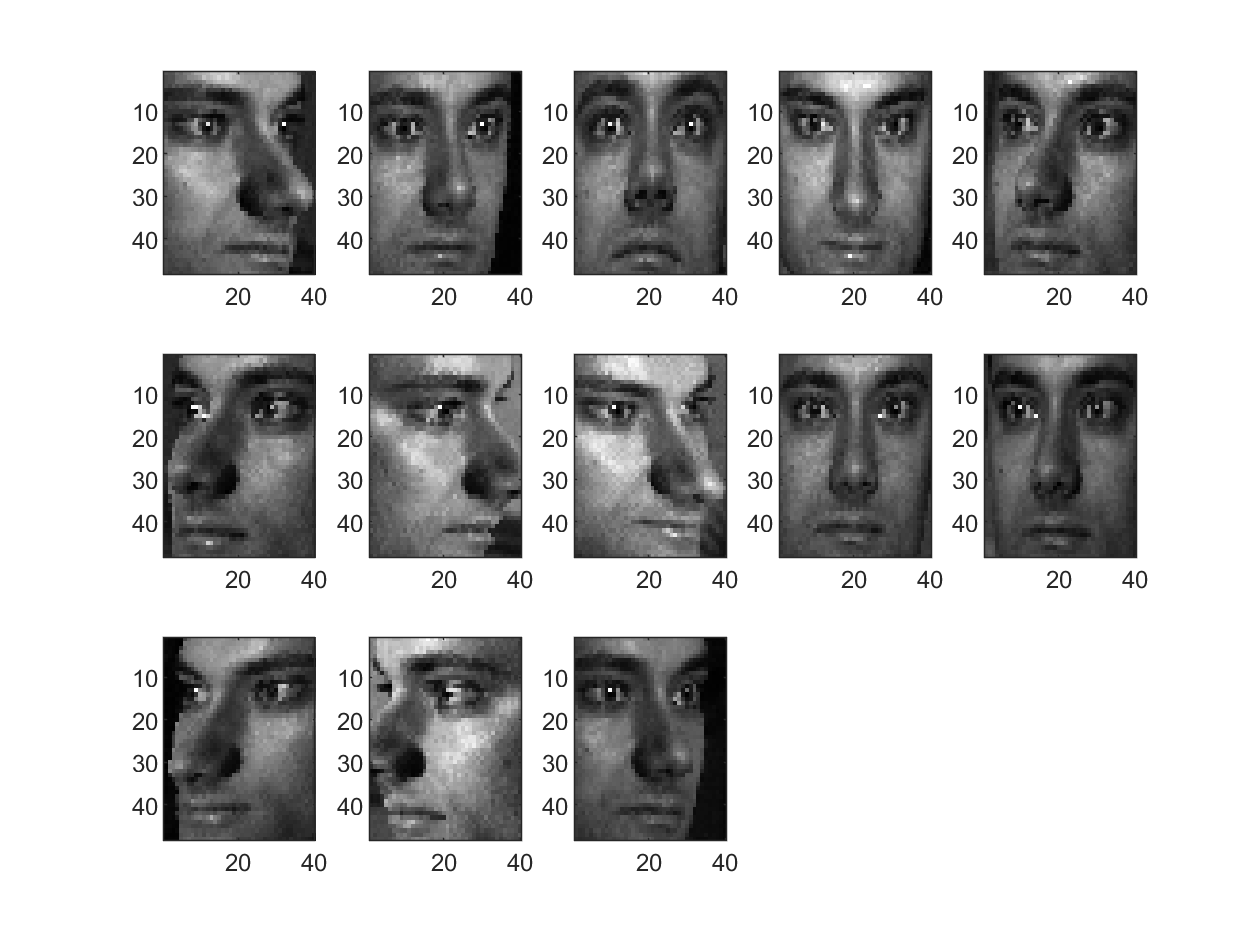

for j = 1:13
    subject2 = subplot(3,5,j);imagesc(reshape(pose(:,:,j,2),[48 40]));
end

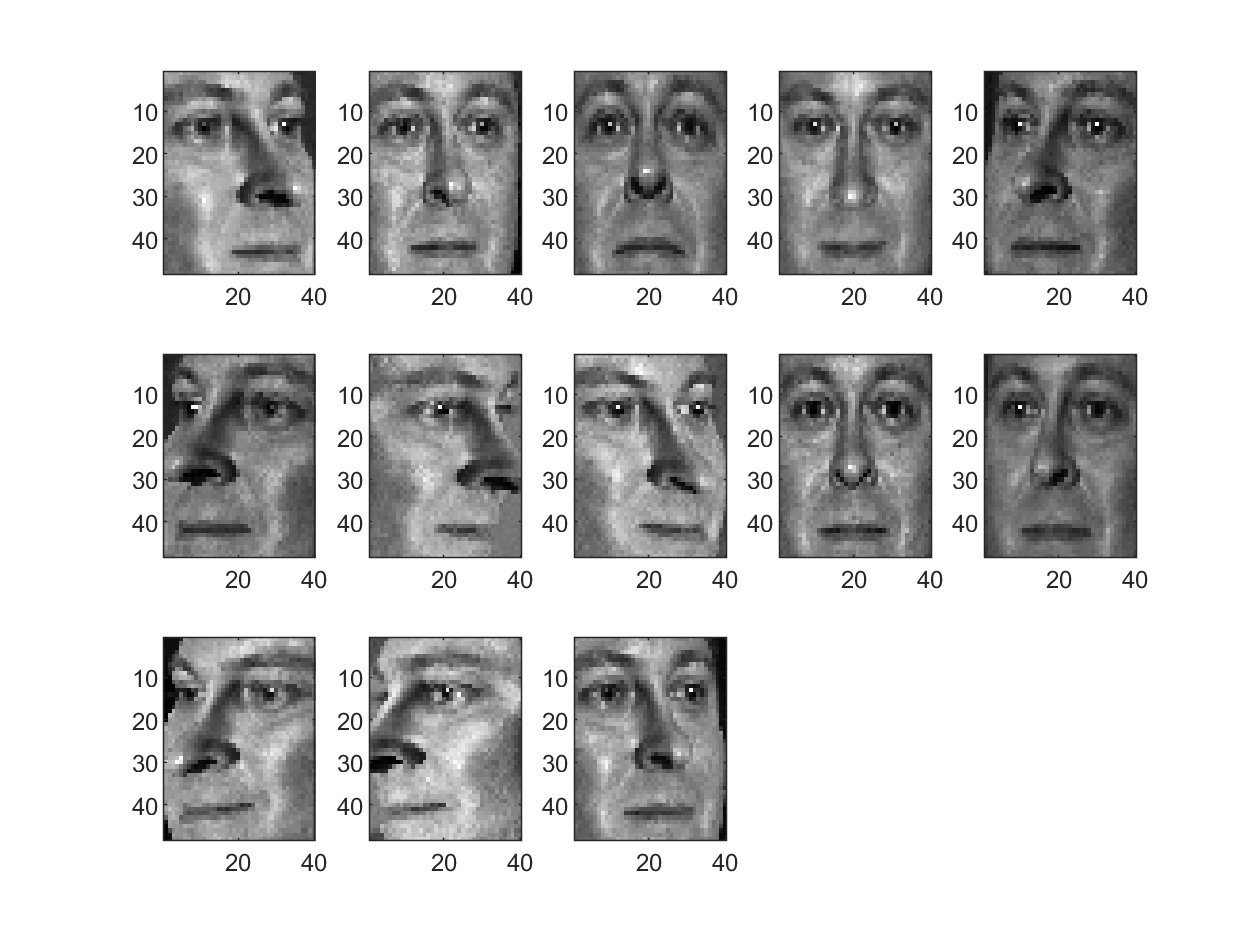

figure; %subject 3 images -- all 13 poses
colormap gray
for j = 1:13
    subject3 = subplot(3,5,j);imagesc(reshape(pose(:,:,j,3),[48 40]));
end

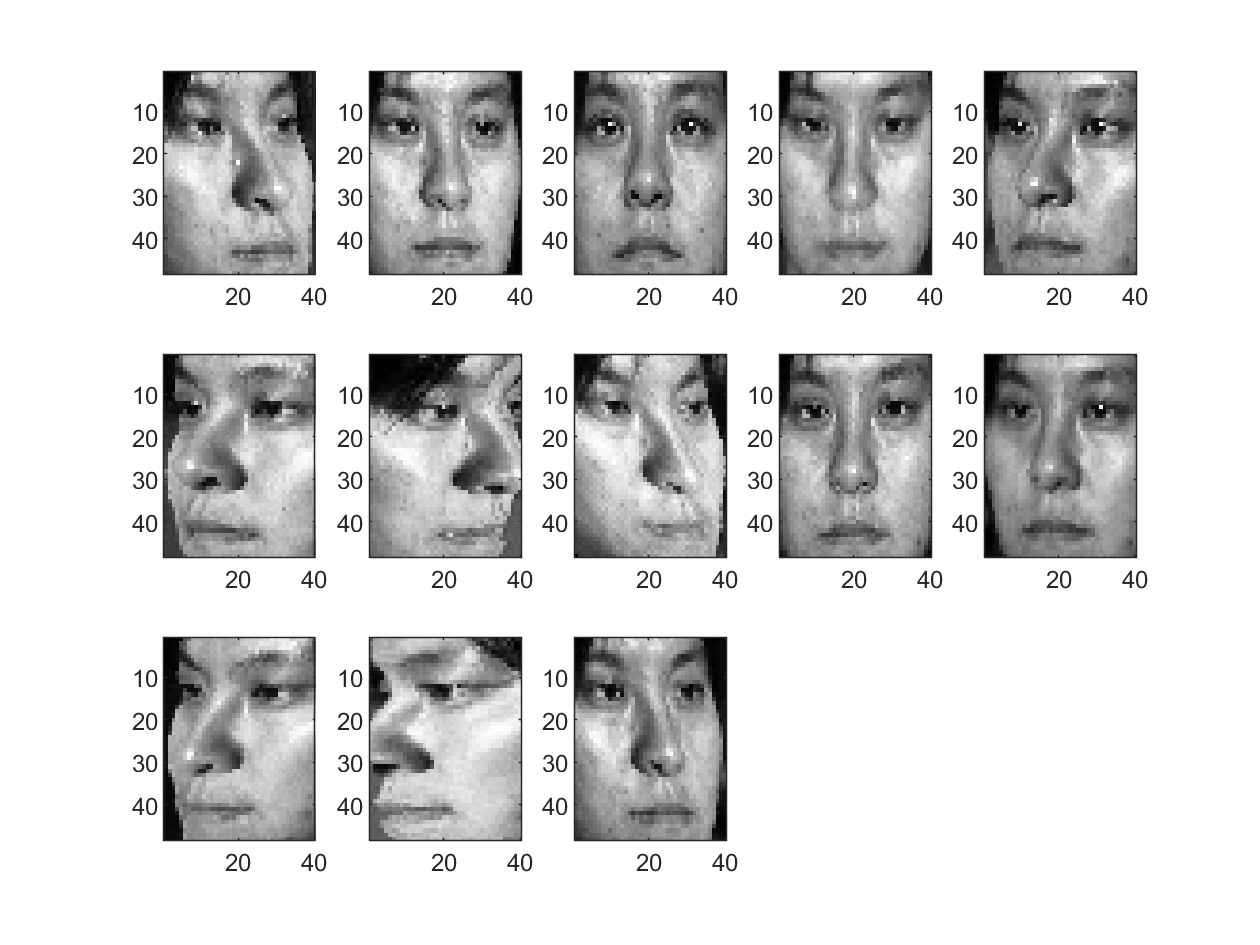

figure; %subject 4 images -- all 13 poses -- class4
colormap gray
for j = 1:13
    subject4 = subplot(3,5,j);imagesc(reshape(pose(:,:,j,4),[48 40]));
end

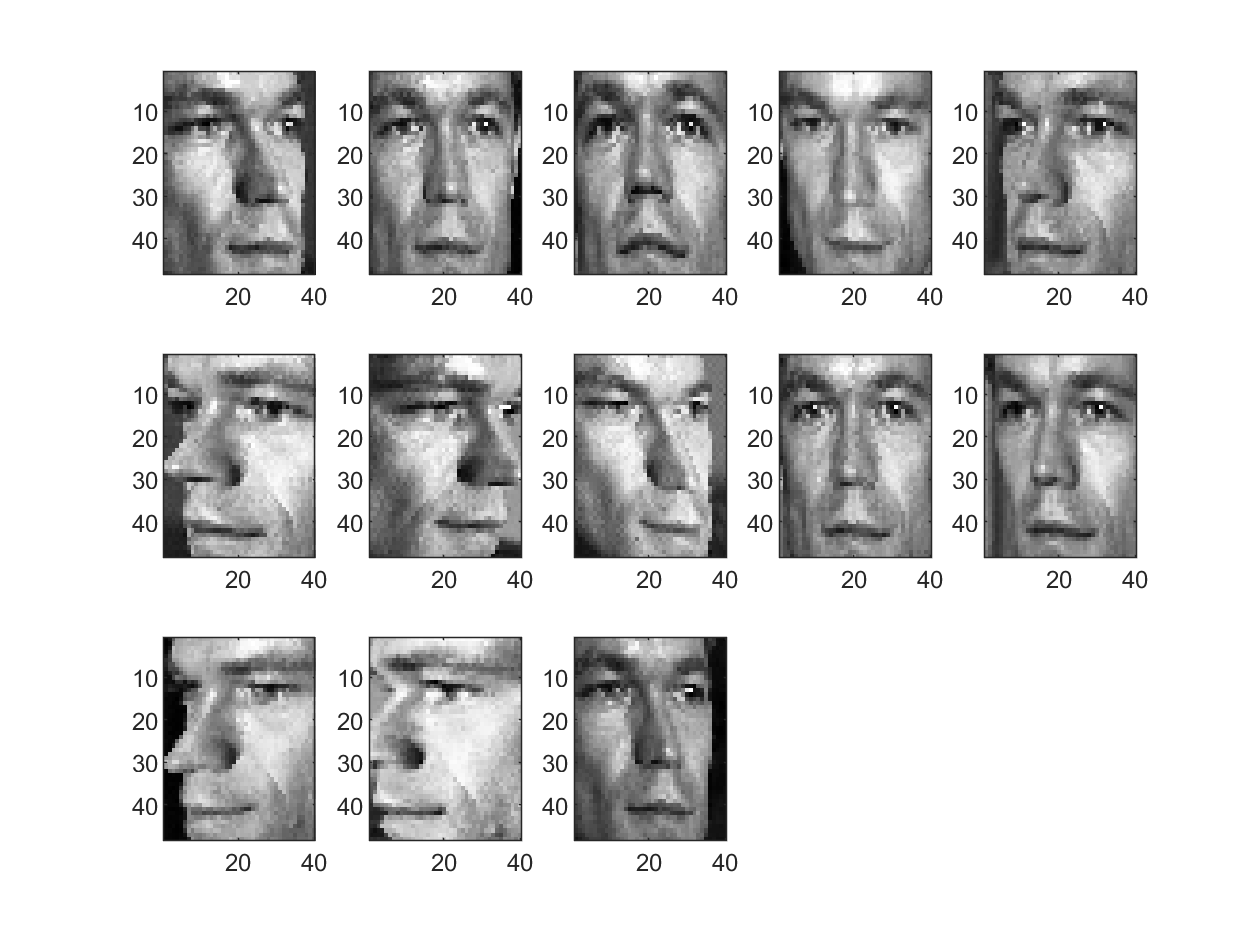

figure; %subject 5 images -- all 13 poses -- class 5
colormap gray
for j = 1:13
    subject5 = subplot(3,5,j);imagesc(reshape(pose(:,:,j,5),[48 40]));
end

size(pose(:,:,:,1:5))

ans =     48    40    13     5


first4Subjects = pose(:,:,:,1:4);

#### **PCA **

[d1, d2, d3, n] = size(first4Subjects);
X1 = zeros(d3*n, d1*d2);%data for subject 1 poses
X2 = zeros(d3*n,d1*d2);%data for subject 2 poses
for j = 1:d3*n
    aux = first4Subjects(:,:,:,j);
    X1(j,: ) = aux(:)';
end

Unable to perform assignment because the size of the left side is 1-by-1920 and the size of the right side is 1-by-24960.


n1 = n;
n2 = n;
m1 = mean(X1,1);%column mean for X1
m2 = mean(X2,1);%column mean for X2
Xc1 = X1-ones(n1,1)*m1; %center X1
S1 = Xc1'*Xc1; %scatter matrix for X1
Xc2 = X2-ones(n2,1)*m2; %center X2
S2 = Xc2'*Xc2;%scatter matrix for X2
Sw = S1+S2;%compute the within-class scatter
%note: d = m*m > n, hence we solve the generalized eigenvalue problem.

Sb = (m1-m2)'*(m1-m2);
[W,lam0] = eig(Sb,Sw);
lam = diag(lam0);
[lam, isort] = sort(lam,'descend');

W = W(:,isort);
W = W(:,1);
X = [X1;X2];
D1 = 1:n1;
D2 = n1+1:n1+n2;
y = X*W;

[U,Sig,V] = svd(X','econ');
nPCA = 20 ;
%project to nPCA-dimensional space
Y = X*U(:,1:nPCA);

figure;
hold on;
grid;
scatter()
plot1(Y(D1,1),'.','Markersize',20,'color','k');
view(3);
plot3(Y(D2,1),Y(D2,2),Y(D2,3),'.','Markersize',20,'color','r');
view(3);%makes plot 3D

**MDA**

 %Find the means and scatters for each subject
 classmean = zeros(ns,nPCA);
 classscatter = zeros(nPCA,nPCA,ns);
 for j = 1:ns
     j1 = ntr*(j-1)+1;%starting index
     jf = ntr*j; %finishing index
     classmean(j,:) = mean(Y(j1:jf,:),1);
     Ycj = Y(j1:jf,:) - ones(ntr,1)*classmean(j,:); %center each class
     classscatter(:,:,j) = Ycj'*Ycj;
 end
 
 mtotal = mean(Y,1); %the total mean vector
 Sw = sum(classscatter,3); %within-class scatter
 Yc = Y-ones(size(Y,1),1)*mtotal;
 Stotal = Yc'*Yc;%the total scatter matrix
 Sb = Stotal - Sw; %between-class scatter
 [evec, eval] = eig(Sb, Sw);
 [esort, isort] = sort(diag(eval),'descend');
 figure;
 plot(escort,'.','Markersize',20);

### **Bayes Theorem**